clear
%load handel
file_path = 'anagha.m4a';
[y, fs] = audioread(file_path);
time = length(y)./fs; % time in seconds
T = 1/fs;           % Sampling period
t = 0:T:time; 
t = t(1:end-1);
y = y(:, 1);

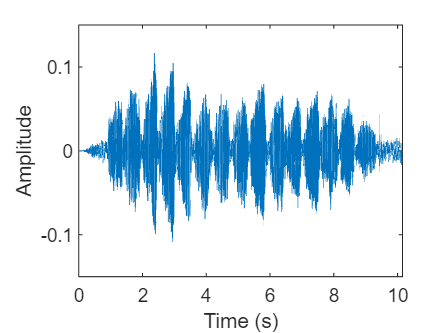

figure
plot(t, y)
xlabel('Time (s)')
ylabel('Amplitude')
hold off;

time_step = .25; % in seconds
steps = time/time_step;
round_step = floor(steps);
index = round(length(y)/ steps);
start_index = 1;
end_index = 1;
highest_freq = [];


for i = 1:round_step
   
    end_index = end_index + index;
    start_index = end_index - index;
    segment = y(start_index : end_index-1);
    n = length(segment);
    y0 = fftshift(fft(segment));         % shift y values
    f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
    amp = abs(y0).^2/n;    % 0-centered amplitude
%     figure
%     plot(f0,amp);
%     xlabel('Frequency')
%     ylabel('Amplitude')
%     xlim([-.1e4/2, .1e4/2])
%     hold off;
    [amp_val, amp_indx] = sort(amp,'descend');
    highest_freq(1,i) = f0(amp_indx(2));
    highest_freq(2,i) = time_step*(i);


end
hold off

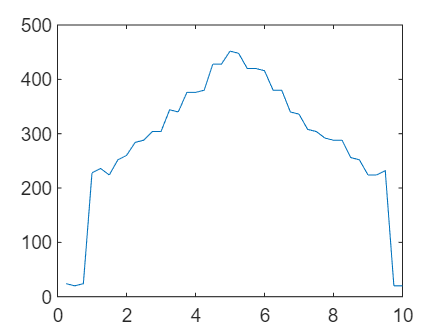

figure
plot(highest_freq(2,:), highest_freq(1,:))

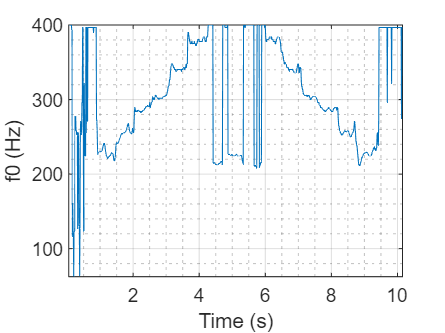



figure()
hold off
pitch(y, fs)